clear
I = im2double(im2gray(imread("red_cell.jpg")));

% 添加椒盐噪声，如果输入为三通道图，会加上彩色的椒盐噪声
I_noise_salt = imnoise(I, "salt & pepper");
% 添加高斯噪声
I_noise_gauss = imnoise(I, "gaussian");

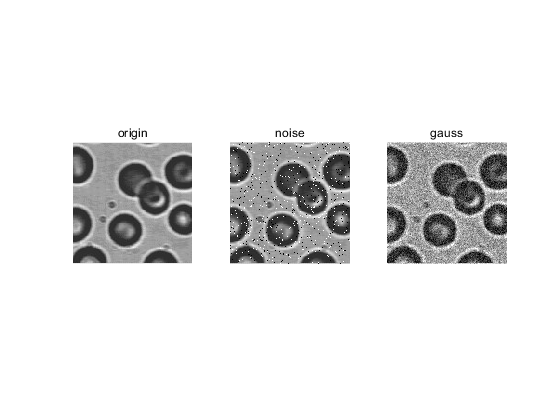

figure, subplot(1,3,1),imshow(I),title("origin");
subplot(1,3,2),imshow(I_noise_salt),title("noise");
subplot(1,3,3),imshow(I_noise_gauss), title("gauss");

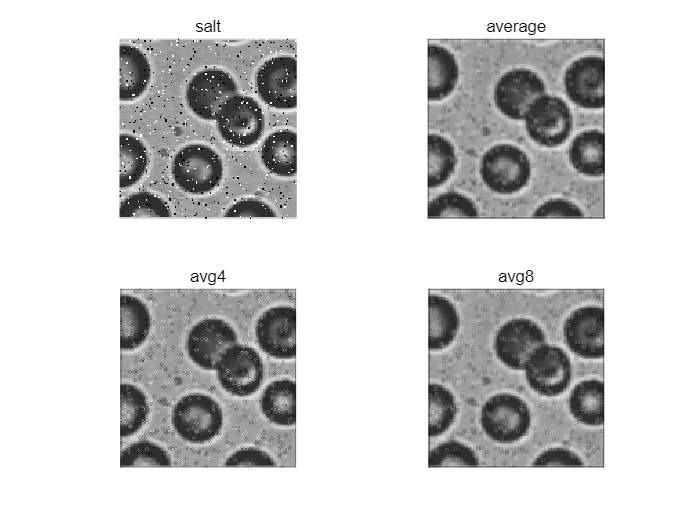

%  生成模板
h_avg = fspecial("average");
% 4邻域平均
h_avg4 = 1/4 * [0,1,0;
    1,0,1;
    0,1,0];
% 8邻域平均
h_avg8 = 1/8 * [1,1,1;
    1,0,1;
    1,1,1];

I_avg = filter2(h_avg, I_noise_salt);
I_avg4 = filter2(h_avg4, I_noise_salt);
I_avg8 = filter2(h_avg8, I_noise_salt);

figure(),subplot(2,2,1),imshow(I_noise_salt), title("salt");
subplot(2,2,2), imshow(I_avg), title("average");
subplot(2,2,3),imshow(I_avg4), title("avg4");
subplot(2,2,4),imshow(I_avg8),title("avg8");

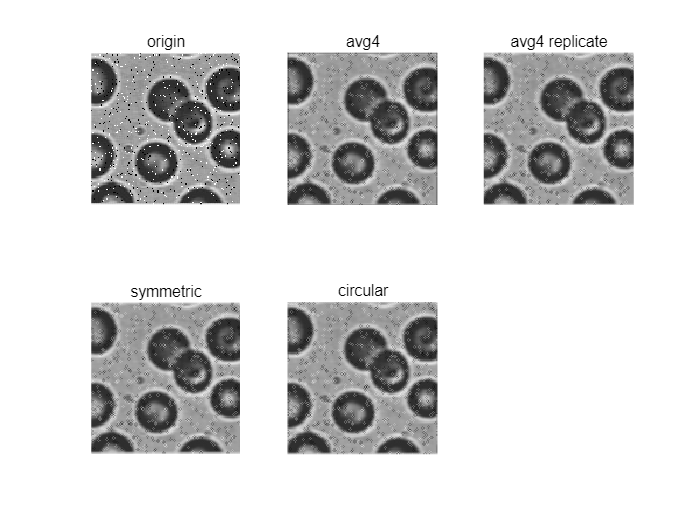

% 不设置选项时默认边缘填充0
I_avg4_zero = imfilter(I_noise_salt, h_avg4);
% 数组边界之外的输入数组值假定为等于最近的数组边界值。
I_avg4_replicate = imfilter(I_noise_salt, h_avg4, "replicate");
% 数组边界之外的输入数组值是通过沿数组边界对数组进行镜面反射得到
I_avg4_symmetric = imfilter(I_noise_salt, h_avg4, "symmetric");
% 向左边拓展时取最右边的值，向右边拓展时取最左边的值
I_avg4_circular = imfilter(I_noise_salt, h_avg4, "circular");

figure(),subplot(2,3,1),imshow(I_noise_salt),title("origin");
subplot(2,3,2),imshow(I_avg4), title("avg4");
subplot(2,3,3), imshow(I_avg4_replicate), title("replicate");
subplot(2,3,4), imshow(I_avg4_symmetric), title("symmetric");
subplot(2,3,5), imshow(I_avg4_circular), title("circular");

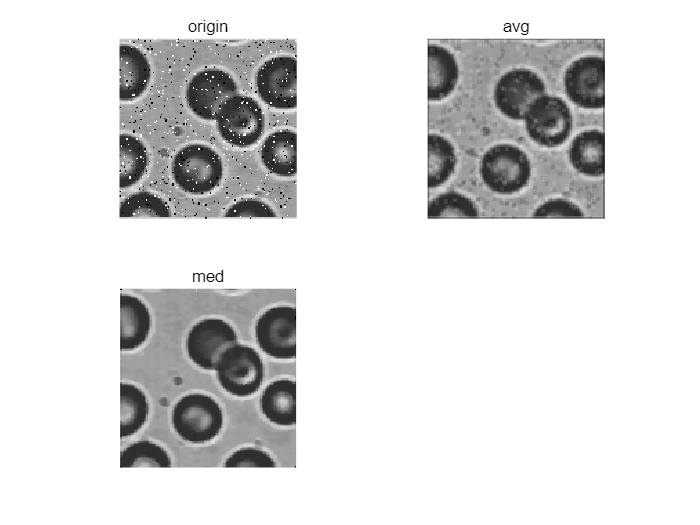

% 均值滤波和中值滤波
h_avg = fspecial("average");
I_avg = imfilter(I_noise_salt,  h_avg);
I_med = medfilt2(I_noise_salt);
figure(), subplot(2,2,1),imshow(I_noise_salt), title("origin");

subplot(2,2,2),imshow(I_avg), title("avg");
subplot(2,2,3),imshow(I_med), title("med");

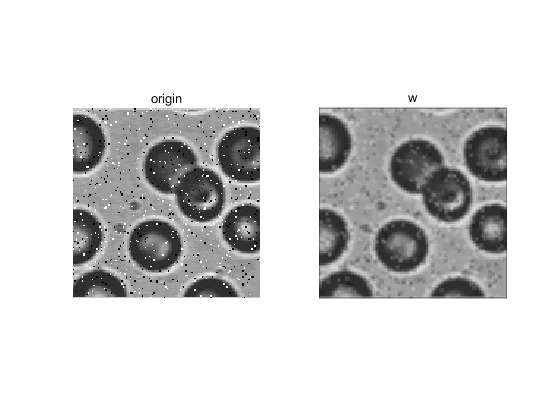

% 邻域加权平均
h_w = 1/10*[
    1,1,1;
    1,2,1;
    1,1,1];
I_w = imfilter(I_noise_salt, h_w);
figure(), subplot(1,2,1),imshow(I_noise_salt), title("origin");
subplot(1,2,2),imshow(I_w), title("w");


clear
I = im2double(im2gray(imread("flower.jpg")));

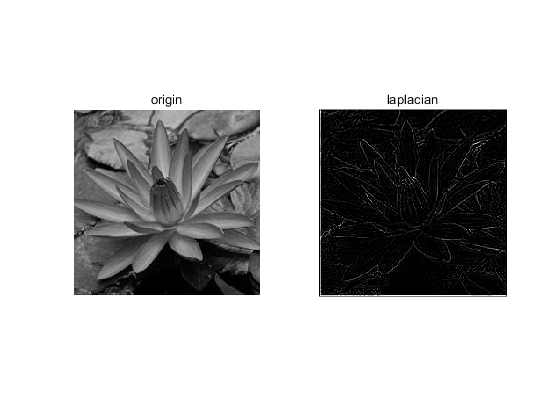

% 用3x3拉普拉斯算子滤波
h_lap = fspecial("laplacian");
I_lap = imfilter(I, h_lap);
figure(), subplot(1,2,1), imshow(I),title("origin");
subplot(1,2,2), imshow(I_lap), title("laplacian");

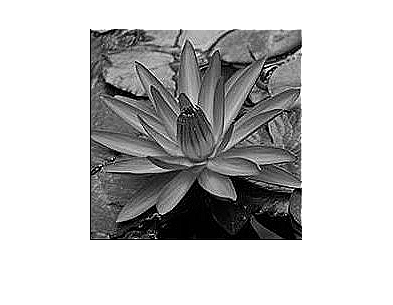

figure(), imshow(I - I_lap);

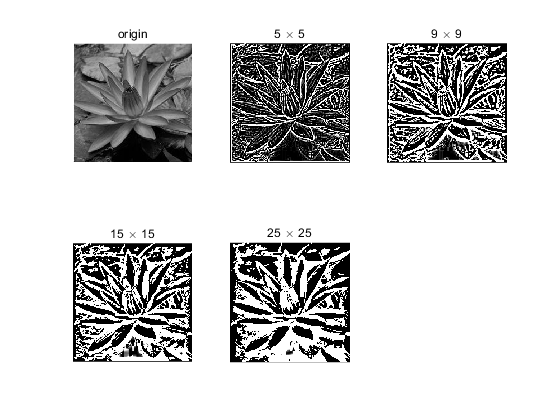

% laplacian变化
clear
% 因为genlaplacian返回值不是0-1的浮点型，因此读入图片也不做im2double操作了
I = im2gray(imread("flower.jpg"));


l_5 = genlaplacian(5);
mask_5 = imfilter(I, l_5);
I_lap_5 = I - mask_5;

l_9 = genlaplacian(9);
mask_9 = imfilter(I, l_9);
I_lap_9 = I - mask_9;

l_15 = genlaplacian(15);
mask_15 = imfilter(I, l_15);
I_lap_15 = I - mask_15;

l_25 = genlaplacian(25);
mask_25 = imfilter(I, l_25);
I_lap_25 = I - mask_25;

figure(), subplot(2,3,1), imshow(I), title("origin");
subplot(2,3,2), imshow(mask_5),title("5 \times 5");
subplot(2,3,3), imshow(mask_9),title("9 \times 9");
subplot(2,3,4), imshow(mask_15),title("15 \times 15");
subplot(2,3,5), imshow(mask_25),title("25 \times 25");

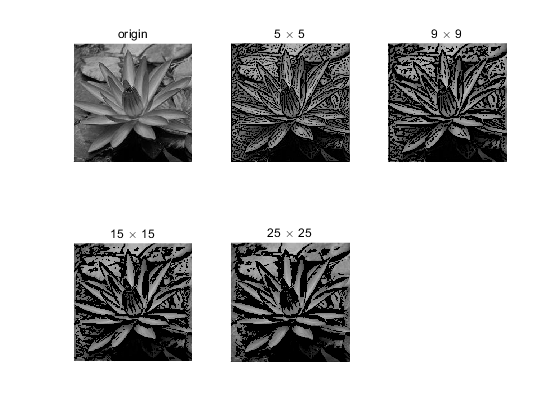

figure(), subplot(2,3,1), imshow(I), title("origin");
subplot(2,3,2), imshow(I_lap_5),title("5 \times 5");
subplot(2,3,3), imshow(I_lap_9),title("9 \times 9");
subplot(2,3,4), imshow(I_lap_15),title("15 \times 15");
subplot(2,3,5), imshow(I_lap_25),title("25 \times 25");

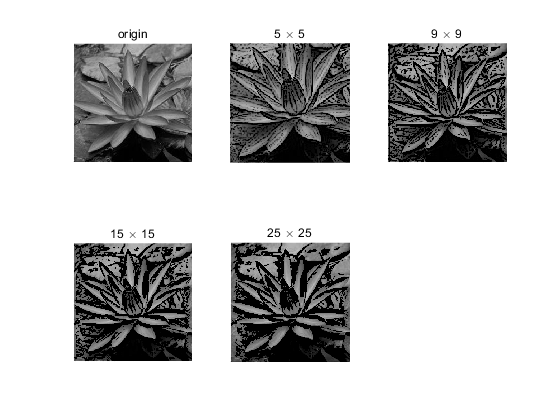

% laplacian变化,算子系数1/3
clear
% 因为genlaplacian返回值不是0-1的浮点型，因此读入图片也不做im2double操作了
I = im2gray(imread("flower.jpg"));


l_5 = 1/3 * genlaplacian(5);
mask_5 = imfilter(I, l_5);
I_lap_5 = I - mask_5;

l_9 = 1/3 * genlaplacian(9);
mask_9 = imfilter(I, l_9);
I_lap_9 = I - mask_9;

l_15 = 1/3 * genlaplacian(15);
mask_15 = imfilter(I, l_15);
I_lap_15 = I - mask_15;

l_25 = 1/3 *genlaplacian(25);
mask_25 = imfilter(I, l_25);
I_lap_25 = I - mask_25;

figure(), subplot(2,3,1), imshow(I), title("origin");
subplot(2,3,2), imshow(I_lap_5),title("5 \times 5");
subplot(2,3,3), imshow(I_lap_9),title("9 \times 9");
subplot(2,3,4), imshow(I_lap_15),title("15 \times 15");
subplot(2,3,5), imshow(I_lap_25),title("25 \times 25");

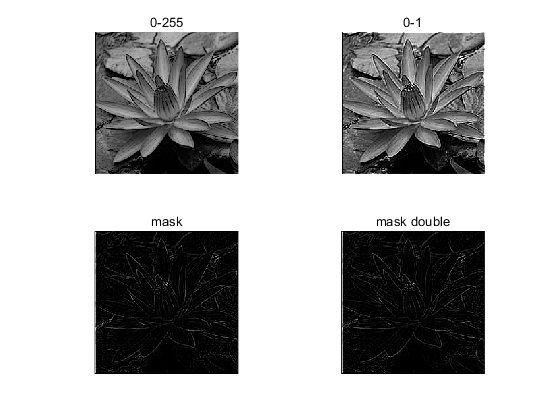

clear
I_rgb = imread("flower.png");
I_gray = rgb2gray(I_rgb);
I_gray_double = im2double(I_gray);
h_lap = 1/3 * genlaplacian(3);

mask = imfilter(I_gray, h_lap);
mask_double = imfilter(I_gray_double, h_lap);

I_lap = I_gray - mask;
I_lap_double = I_gray_double - mask_double;

figure(),subplot(2,2,1),imshow(I_lap),title("0-255");
subplot(2,2,2),imshow(I_lap_double),title("0-1");
subplot(2,2,3),imshow(mask),title("mask");
subplot(2,2,4),imshow(mask_double),title("mask double");

mask_double(mask_double < 0) = 0;
mask_double = mask_double * 255;

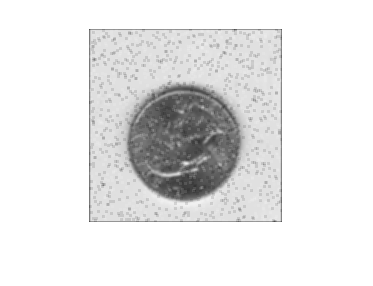

h = fspecial("average");
n = imfilter(n, h);
imshow(n)

I = im2double(imread("flower.png"));
h = genlaplacian(3)

h =      1     1     1
     1    -8     1
     1     1     1


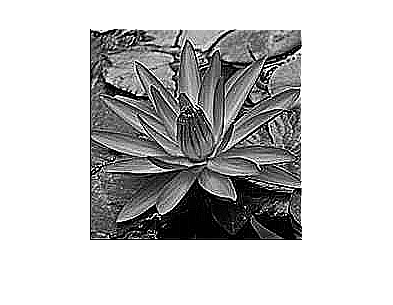

mask = imfilter(I, h);
figure(), imshow(I-mask)

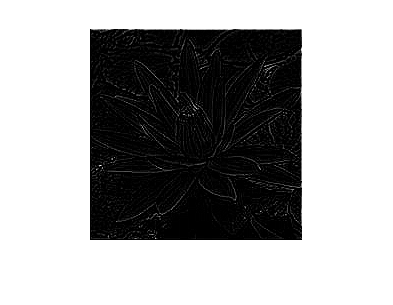

ans =    -0.2500   -0.5000   -0.2500
   -0.5000    3.0000   -0.5000
   -0.2500   -0.5000   -0.2500


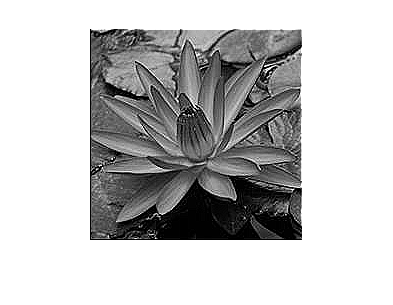

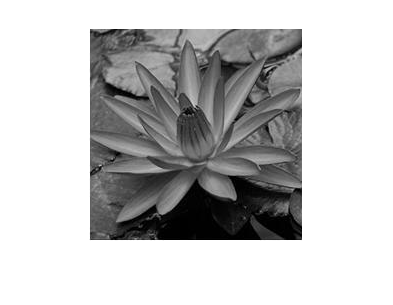

h = -fspecial("laplacian");
I_addmask = imfilter(I, h);
imshow(I_addmask);